folder = '..//..//Data//registration_data//coc_collagen_us//Run-1-beamformed';
% save_folder = 'coc_collagen_us//Run-1-tiffs';
files = dir(folder);
files = files(3:end);
load(fullfile(folder,files(end).name),'Trans','Receive')
load(fullfile(folder,files(1).name))
xs = ((-(Trans.numelements/2 -1):(Trans.numelements/2))-0.5)*Trans.spacingMm;
xs = xs(14:115);
fs=Receive(1).decimSampleRate;
dt = 1/fs;
ts = (0:(length(IQData)-1))*dt;
zs = 1.48*ts/2;
dx = xs(2) - xs(1);
dz = zs(2) - zs(1);
zmask = zs > 5 & zs <9 ;
depth_val = length(zs(zmask));
data = zeros(102,length(files)-1,length(zs(zmask)));

for i=1:(length(files)-1)
    load(fullfile(folder,files(i).name))
    if ~isnan(str2double(files(i).name(23:25)))
        num_label = files(i).name(23:25);
    elseif ~isnan(str2double(files(i).name(23:24)))
        num_label = files(i).name(23:24);
    else
        num_label = files(i).name(23);
    end

    index = str2num(num_label);



    % Bmode = uint16(20*log10(abs(IQData(zmask,:))+1) *65535/100);
    Bmode = 20*log10(abs(IQData(zmask,:))+1);

    % imagesc(xs,zs(zmask),Bmode)
    % colormap gray
    % xs
    % imwrite(Bmode, fullfile(save_folder,[num_label '.tif']), 'tif','Compression', 'none');
    data(:,index,:) = Bmode.';
end

pos_file = '..//..//Data//registration_data//US_PositionList_registration.pos';
jsonText = fileread(pos_file);
datastruct = jsondecode(jsonText);
pos_struct = datastruct.map.StagePositions.array;
% pos_struct(1).Label.scalar
positions = zeros(length(files)-1,2);
for i=1:(length(files)-1)
    positions(i,:) = pos_struct(i).DevicePositions.array.Position_um.array'/1000;
end

pos = cell(2,1);
pos{1} = positions(1:138,:);
pos{2} = positions(139:end,:);

data_cell = cell(2,1);
data_cell{1} = data(:,1:138,:);
data_cell{2} = data(:,139:end,:);


xs1 = xs;
ys1 = -(pos{1}(:,2).');
zs1 = zs(zmask);
% xs1 = reshape(xs,[102 1 1]);
% ys1 = reshape(pos{1}(:,2).',[1 201 1]);
% zs1 = reshape(zs(zmask),[1 1 845]);
% X = repmat(xs1,[1 201 845]);
% Y = repmat(ys1,[102 1 845]);
% Z = repmat(zs1,[102 201 1]);

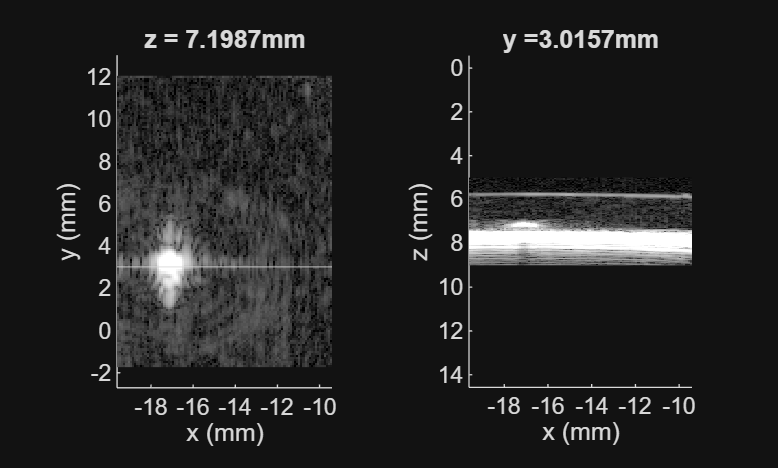

j = 91;
k = 186;
dynamic_range = [4 60];
% figure()
figure();tiledlayout(1,2);nexttile;
hold on
for l=1:2
    imagesc(xs + pos{l}(1),ys1,(squeeze(data_cell{l}(:,:,k)).'),dynamic_range)
end
yline(ys1(j))
hold off
% imagesc(xs,zs(zmask),squeeze(data_cell{1}(:,j,:)).')
% xlim([-20 5])
colormap gray
axis equal
title(['z = ' num2str(zs1(k)) 'mm'])
xlabel('x (mm)')
ylabel('y (mm)')

nexttile
hold on
set(gca, 'YDir', 'reverse');
for l=1:2
    imagesc(xs + pos{l}(1),(zs(zmask)),(squeeze(data_cell{l}(:,j,:)).'),dynamic_range)
end
hold off
title(['y =' num2str(ys1(j)) 'mm'])
xlabel('x (mm)')
ylabel('z (mm)')
axis equal
colormap gray

% end


folder = '..//..//Data//registration_data//coc_collagen_shg';
% save_folder = 'Registration2025-11-11//Run-1-tiffs';
files = dir([folder '//*.tif']);
% files = files(3:end);
files_positions_shg = arrayfun(@(i) files(i).name(37:45),1:length(files),'UniformOutput',false);



pos_file_shg = '..//..//Data//registration_data//SHG_collagen_list.pos';
jsonText_shg = fileread(pos_file_shg);
datastruct_shg = jsondecode(jsonText_shg);
pos_struct_shg = datastruct_shg.map.StagePositions.array;
% pos_struct(1).Label.scalar
positions_shg = zeros(length(pos_struct_shg),2);
positions_shg_labels = cell(length(pos_struct_shg),1);
for i=1:(length(pos_struct_shg))
    positions_shg(i,:) = pos_struct_shg(i).DevicePositions.array.Position_um.array'/1000;
    positions_shg_labels{i} = pos_struct_shg(i).Label.scalar;
end
dx_shg = 262.4/256 /1000;
xs_shg = (0:255) * dx_shg;
ys_shg = xs_shg;

% volumeData = tiffreadVolume(fullfile(folder,files(1).name));

tifdata = zeros(length(positions_shg_labels),256,256,51);
for i=1:length(files)
    volumeData = tiffreadVolume(fullfile(folder,files(i).name));
    target_pos = files_positions_shg{i};
    for j=1:length(positions_shg_labels)
        if strcmp(target_pos,positions_shg_labels{j})
            tifdata(j,:,:,:) = volumeData;
        end
    end
end

x_transform = @(x) 0.98*x - 0.4840;
y_transform = @(y) 1.0030*y + 1.0196;
z_transform = @(z) z+7;
zs_shg = (0:10:500)*0.001;

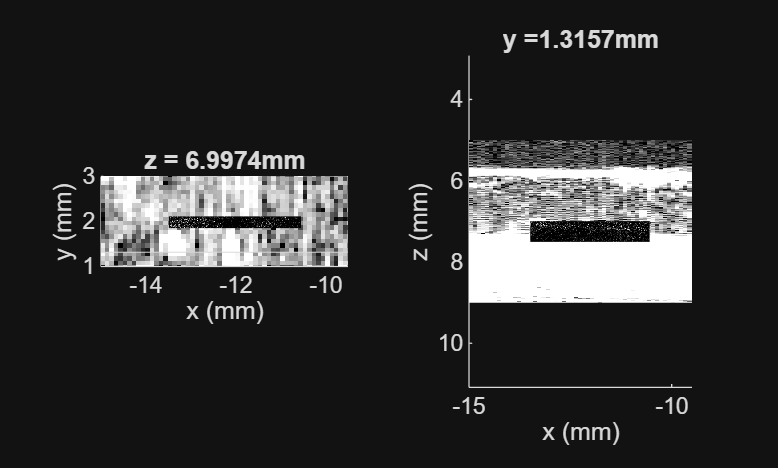

j = 256;
k = 51;
zus_target = z_transform(zs_shg(52-k));
yus_target = y_transform(ys_shg(j));
kus = find(abs(zs1 - zus_target) == min(abs(zs1 - zus_target)));
jus = find(abs(ys1 - yus_target) == min(abs(ys1 - yus_target)));
contrast = [4 21];

% jus = 100;
% kus = 165;
dynamic_range = [4 60];



% figure()
figure();tiledlayout(1,2);nexttile;
hold on
for l=1:2
    imagesc(xs + pos{l}(1),ys1,(squeeze(data_cell{l}(:,:,kus)).'),dynamic_range)
end
yline(ys1(jus))
hold off
% imagesc(xs,zs(zmask),squeeze(data_cell{1}(:,j,:)).')
% xlim([-20 5])
colormap gray
axis equal
title(['z = ' num2str(zs1(kus)) 'mm'])
xlabel('x (mm)')
ylabel('y (mm)')

hold on
for i=1:length(positions_shg_labels)
    imagesc(x_transform(xs_shg + positions_shg(i,1)),y_transform(ys_shg + positions_shg(i,2)),squeeze(tifdata(i,:,:,k)),contrast)
end
hold off
map = [zeros(256,1) linspace(0,1,256).' zeros(256,1)];
colormap(map)
axis equal

ylim([1 3])
xlim([-15 -9.5])

nexttile
hold on
set(gca, 'YDir', 'reverse');
for l=1:2
    imagesc(xs + pos{l}(1),(zs(zmask)),(squeeze(data_cell{l}(:,jus,:)).'),dynamic_range)
end
hold off
title(['y =' num2str(ys1(jus)) 'mm'])
xlabel('x (mm)')
ylabel('z (mm)')
axis equal
colormap gray

xlim([-15 -9.5])

hold on
for i=1:length(positions_shg_labels)
    imagesc(x_transform(xs_shg + positions_shg(i,1)),zs_shg +7,flipud(squeeze(tifdata(i,:,j,:)).'),contrast)
end
hold off

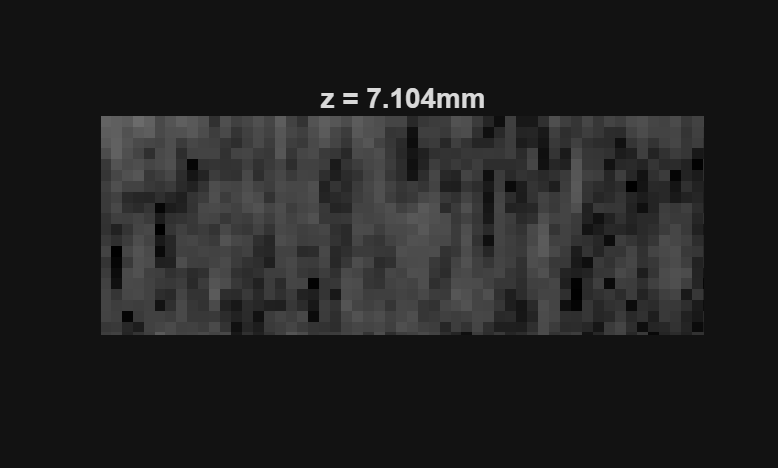

j = 128;
k = 41;
zus_target = z_transform(zs_shg(52-k));
yus_target = y_transform(ys_shg(j));
kus = find(abs(zs1 - zus_target) == min(abs(zs1 - zus_target)));
jus = find(abs(ys1 - yus_target) == min(abs(ys1 - yus_target)));
contrast = [4 19];

% jus = 100;
% kus = 165;
dynamic_range = [4 60];



% figure()
figure()
hold on
for l=1:2
    imagesc(xs + pos{l}(1),ys1,(squeeze(data_cell{l}(:,:,kus)).'),dynamic_range)
end
% yline(ys1(jus))
hold off
% imagesc(xs,zs(zmask),squeeze(data_cell{1}(:,j,:)).')
% xlim([-20 5])
colormap gray
axis equal
title(['z = ' num2str(zs1(kus)) 'mm'])
xlabel('x (mm)')
ylabel('y (mm)')

% hold on
% for i=1:length(positions_shg_labels)
%     imagesc(x_transform(xs_shg + positions_shg(i,1)),y_transform(ys_shg + positions_shg(i,2)),squeeze(tifdata(i,:,:,k)),contrast)
% end
% hold off
% map = [zeros(256,1) linspace(0,1,256).' zeros(256,1)];
% colormap(map)
colormap gray
axis equal
axis off

ylim([1 3])
xlim([-15 -9.5])

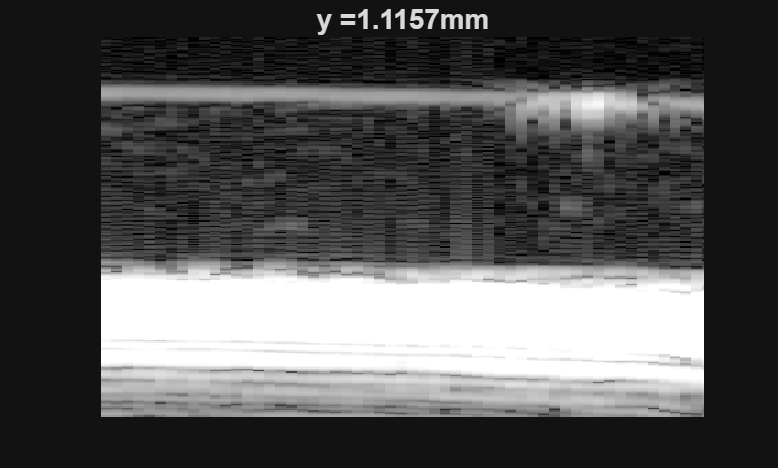


figure()
hold on
set(gca, 'YDir', 'reverse');
for l=1:2
    imagesc(xs + pos{l}(1),(zs(zmask)),(squeeze(data_cell{l}(:,jus,:)).'),dynamic_range)
end
hold off
title(['y =' num2str(ys1(jus)) 'mm'])
xlabel('x (mm)')
ylabel('z (mm)')
axis equal
axis off
colormap gray

xlim([-15 -9.5])

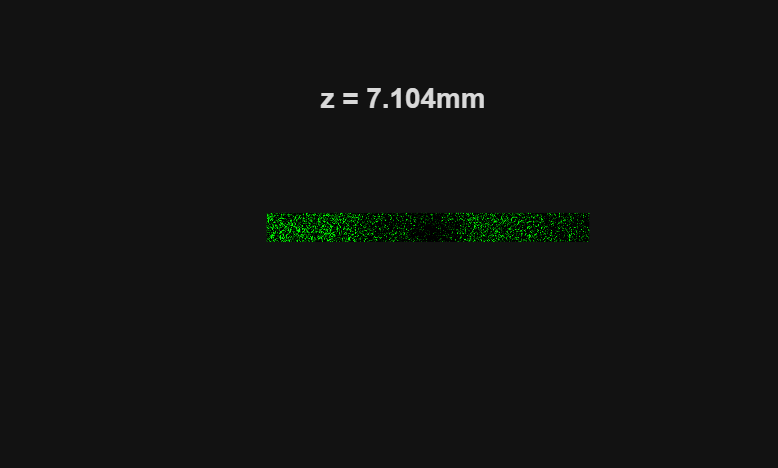


% hold on
% for i=1:length(positions_shg_labels)
%     imagesc(x_transform(xs_shg + positions_shg(i,1)),zs_shg +7,flipud(squeeze(tifdata(i,:,j,:)).'),contrast)
% end
% hold off

figure()
% hold on
% for l=1:2
%     imagesc(xs + pos{l}(1),ys1,(squeeze(data_cell{l}(:,:,kus)).'),dynamic_range)
% end
% yline(ys1(jus))
% hold off
% imagesc(xs,zs(zmask),squeeze(data_cell{1}(:,j,:)).')
% xlim([-20 5])
% colormap gray
axis equal
title(['z = ' num2str(zs1(kus)) 'mm'])
xlabel('x (mm)')
ylabel('y (mm)')

hold on
for i=1:length(positions_shg_labels)
    imagesc(x_transform(xs_shg + positions_shg(i,1)),y_transform(ys_shg + positions_shg(i,2)),squeeze(tifdata(i,:,:,k)),contrast)
end
hold off
map = [zeros(256,1) linspace(0,1,256).' zeros(256,1)];
colormap(map)
axis equal
axis off

ylim([1 3])
xlim([-15 -9.5])

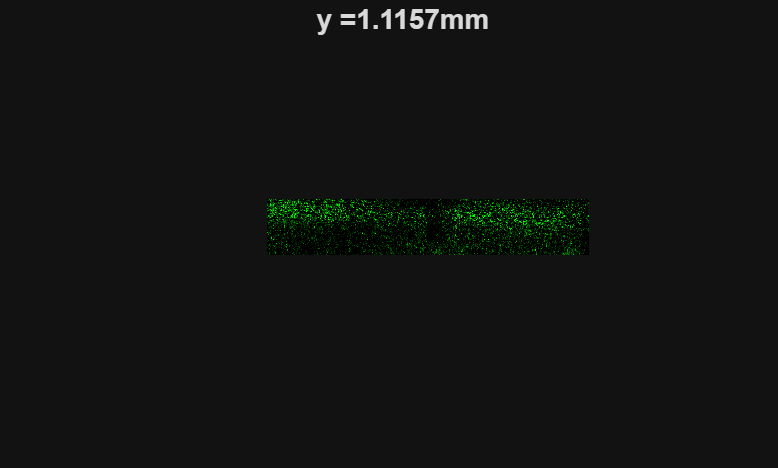


figure()
% hold on
set(gca, 'YDir', 'reverse');
% for l=1:2
%     imagesc(xs + pos{l}(1),(zs(zmask)),(squeeze(data_cell{l}(:,jus,:)).'),dynamic_range)
% end
% hold off
title(['y =' num2str(ys1(jus)) 'mm'])
xlabel('x (mm)')
ylabel('z (mm)')
axis equal
% colormap gray
colormap(map)
xlim([-15 -9.5])

hold on
for i=1:length(positions_shg_labels)
    imagesc(x_transform(xs_shg + positions_shg(i,1)),zs_shg +7,flipud(squeeze(tifdata(i,:,j,:)).'),contrast)
end
hold off
axis off